# Experimento do corpo - Selecionado

### Baseado na derivada do modelo de posição do experimento exp1_corpo

clear
load exp_mc_6.mat

#### Manipulaçao dos dados de entrada e variaveis uteis

max(u)

ans = 29

uni = max(u)/100 * 7.4

uni = 2.1460

u = u / max(u);
yr = yr / uni; % / (30 * 4 * 7) * 2 * pi;
yr = yr - mean(yr);
yl = yl / uni; % / (30 * 4 * 7) * 2 * pi;
yl = yl - mean(yl);
ti = t_trig;
f = freq;
theta = theta / uni * pi / 180;
theta = theta - mean(theta);
ts = 0.01;
l_tempo = "Tempo(s)";
l_pos = "Posição(rad)";
l_vel = "Velocidade(rad/s)";
l_frad = "Frequência(rad/s)";
l_gdec = "|G| dB";

#### Gráficos de posição a partir dos encoders e da MPU

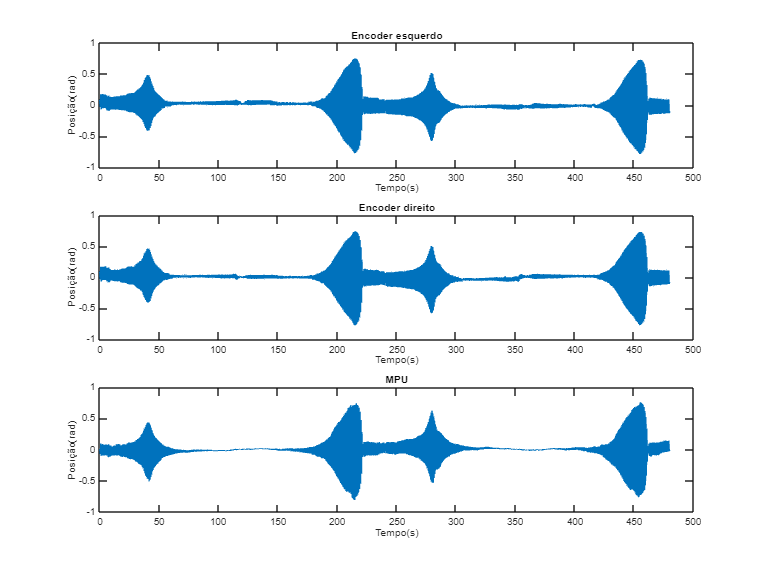

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)*2]);
clear pos
limx = [-2 2];

subplot(3,1,1)
plot(t, yl)
ylabel(l_pos)
xlabel(l_tempo)
title("Encoder esquerdo")

subplot(3,1,2)
plot(t, yr)
ylabel(l_pos)
xlabel(l_tempo)
title("Encoder direito")

subplot(3,1,3)
plot(t, theta)
title("MPU")
ylabel(l_pos)
xlabel(l_tempo)

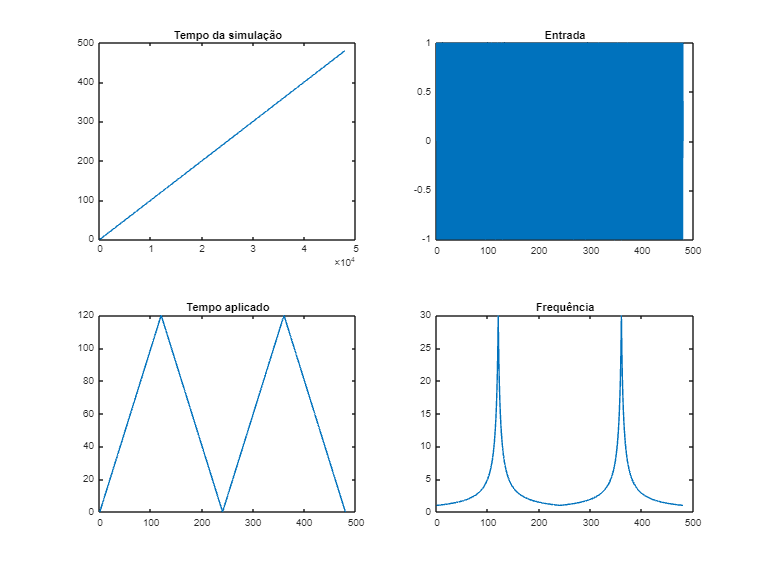

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)*2]);
clear pos

subplot(2,2,1)
plot(t)
title("Tempo da simulação")
subplot(2,2,2)
plot(t, u)
title("Entrada")
subplot(2,2,3)
plot(t, ti)
title("Tempo aplicado")
subplot(2,2,4)
plot(t, f)
title("Frequência")

#### Dados cortados

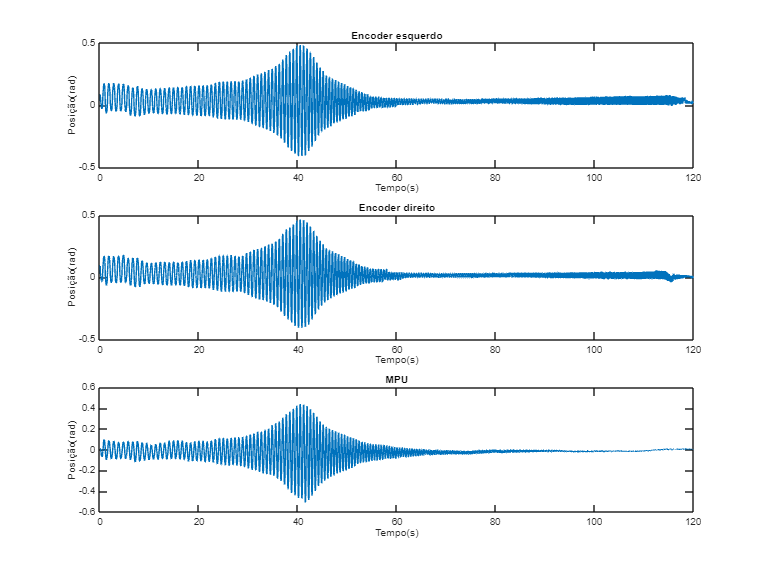

idx = t>t(1) & t<120;
% idx = t>122 & t<240;
% idx = t>0 & t<240;
% idx = t>0 & t<480;

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)*2]);
clear pos

subplot(3,1,1)
plot(t(idx), yl(idx))
ylabel(l_pos)
xlabel(l_tempo)
title("Encoder esquerdo")

subplot(3,1,2)
plot(t(idx), yr(idx))
ylabel(l_pos)
xlabel(l_tempo)
title("Encoder direito")

subplot(3,1,3)
plot(t(idx), theta(idx))
title("MPU")
ylabel(l_pos)
xlabel(l_tempo)

#### Modelos de posição 

dados_encoder_l = iddata(yl(idx), u(idx), ts);
dados_encoder_r = iddata(yr(idx), u(idx), ts);
dados_mpu = iddata(theta(idx), u(idx), ts);
G_encoder_l = tfest(dados_encoder_l, 2, 0)

G_encoder_l =
 
  From input "u1" to output "y1":
          -3.422
  ----------------------
  s^2 + 0.9976 s + 81.26
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                     
Estimated using TFEST on time domain data "dados_encoder_l".
Fit to estimation data: 51.82%                              
FPE: 0.002335, MSE: 0.002333                                
 
Model Properties


G_encoder_r = tfest(dados_encoder_r, 2, 0)

G_encoder_r =
 
  From input "u1" to output "y1":
          -3.314
  ----------------------
  s^2 + 0.9968 s + 81.13
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                     
Estimated using TFEST on time domain data "dados_encoder_r".
Fit to estimation data: 56.16%                              
FPE: 0.001856, MSE: 0.001855                                
 
Model Properties


G_mpu = tfest(dados_mpu, 2, 0)

G_mpu =
 
  From input "u1" to output "y1":
          -3.177
  ----------------------
  s^2 + 0.9096 s + 81.02
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using TFEST on time domain data "dados_mpu".
Fit to estimation data: 60.67%                        
FPE: 0.001489, MSE: 0.001487                          
 
Model Properties


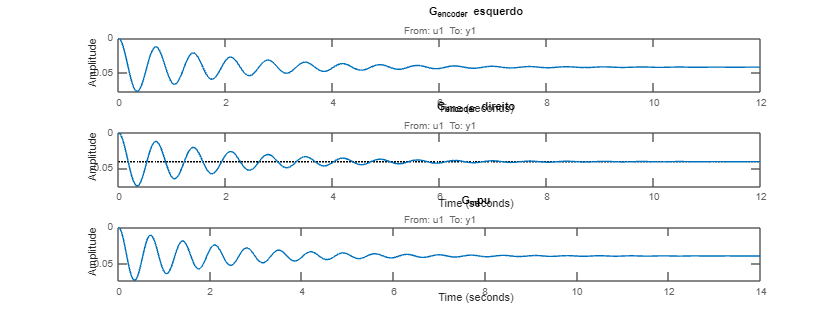

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

subplot(3,1,1)
step(G_encoder_l)
title("G_{encoder} esquerdo")

subplot(3,1,2)
step(G_encoder_r)
title("G_{encoder} direito")

subplot(3,1,3)
step(G_mpu)
title("G_mpu")

#### Comparação dos modelos de posição com os dados experimentais

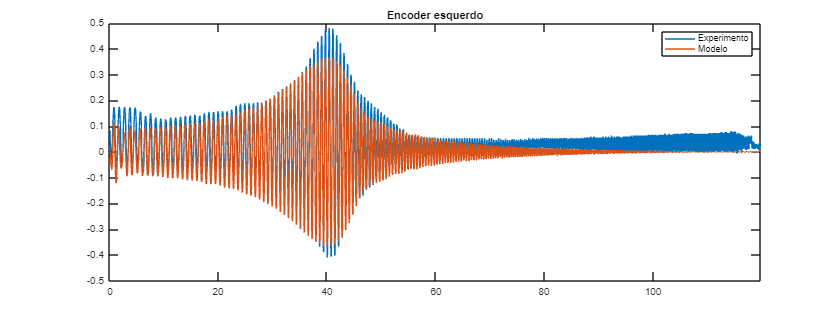

tt = 0:ts:length(u(idx))*ts-ts;
% idx = (length(tt)*7/8:length(tt));

y_encoder_l = lsim(G_encoder_l, u(idx), tt);
y_encoder_r = lsim(G_encoder_r, u(idx), tt);
y_mpu = lsim(G_mpu, u(idx), tt);

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

plot(tt, yl(idx))
title("Encoder esquerdo")
hold on
plot(tt, y_encoder_l)
xlim([tt(1) tt(end)])
legend("Experimento", "Modelo")

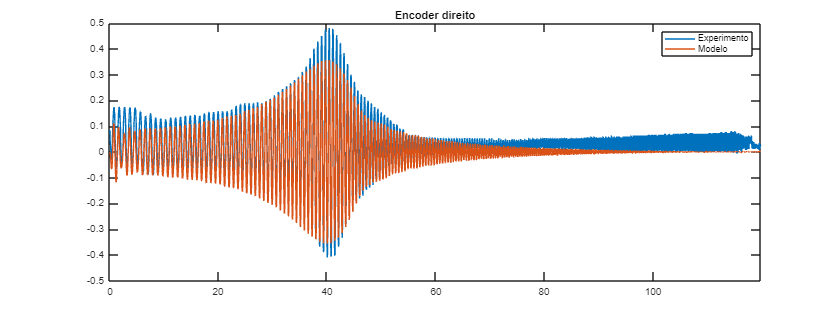


figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

plot(tt, yl(idx))
title("Encoder direito")
hold on
plot(tt, y_encoder_r)
xlim([tt(1) tt(end)])
legend("Experimento", "Modelo")

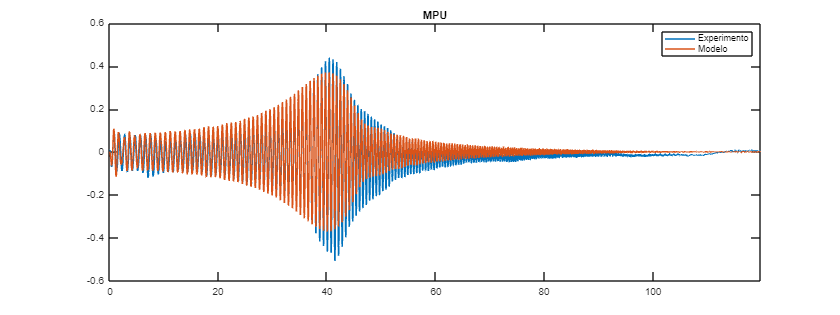


figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

plot(tt, theta(idx))
title("MPU")
hold on
plot(tt, y_mpu)
xlim([tt(1) tt(end)])
legend("Experimento", "Modelo")

#### Calculo das velocidades a partir da posição

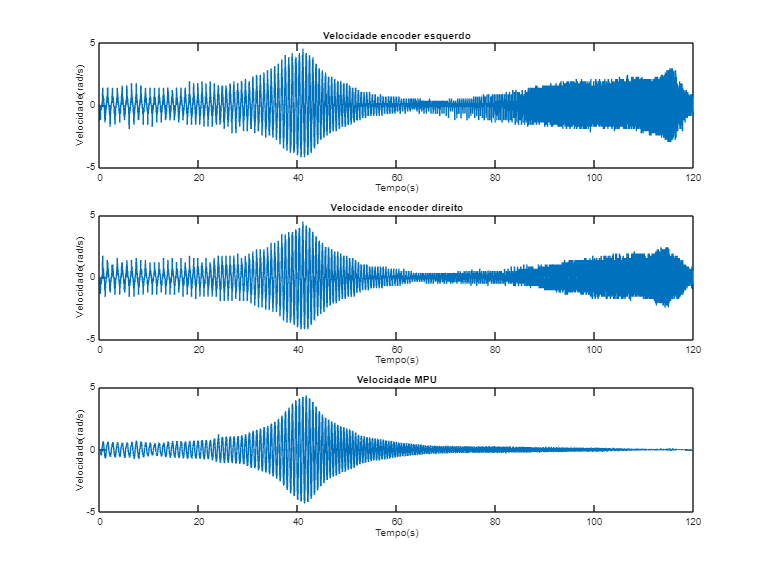

t1 = t(idx);
u1 = u(idx);
yl1 = yl(idx);
yr1 = yr(idx);
f1 = f(idx);
theta1 = theta(idx);

rvel = gradient(yr1) ./ gradient(t1);
lvel = gradient(yl1) ./ gradient(t1);
thetavel = gradient(theta1) ./ gradient(t1);


figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)*2]);
clear pos

subplot(3,1,1)
plot(t1, lvel)
title("Velocidade encoder esquerdo")
xlabel(l_tempo)
ylabel(l_vel)

subplot(3,1,2)
plot(t1, rvel)
title("Velocidade encoder direito")
xlabel(l_tempo)
ylabel(l_vel)

subplot(3,1,3)
plot(t1, thetavel)
title("Velocidade MPU")
xlabel(l_tempo)
ylabel(l_vel)

#### Gráfico de velocidades com frequência

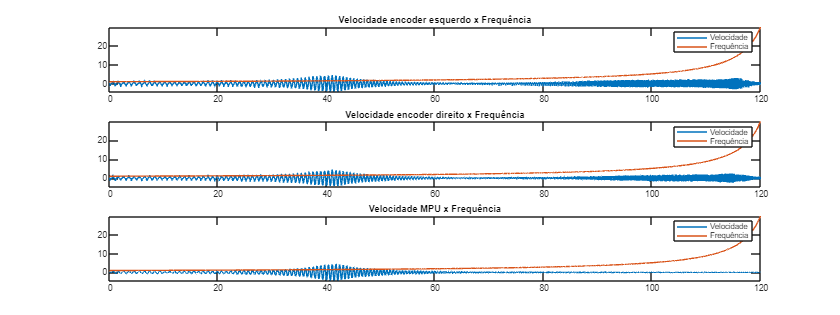

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

x = [t1(1) t1(end)];

subplot(3,1,1)
plot(t1, lvel)
title("Velocidade encoder esquerdo x Frequência")
hold on
plot(t1, f1)
legend(["Velocidade" "Frequência"])

subplot(3,1,2)
plot(t1, rvel)
title("Velocidade encoder direito x Frequência")
hold on
plot(t1, f1)
legend(["Velocidade" "Frequência"])

subplot(3,1,3)
plot(t1, thetavel)
title("Velocidade MPU x Frequência")
hold on
plot(t1, f1)
legend(["Velocidade" "Frequência"])

#### Bode com os dados dos experimentos

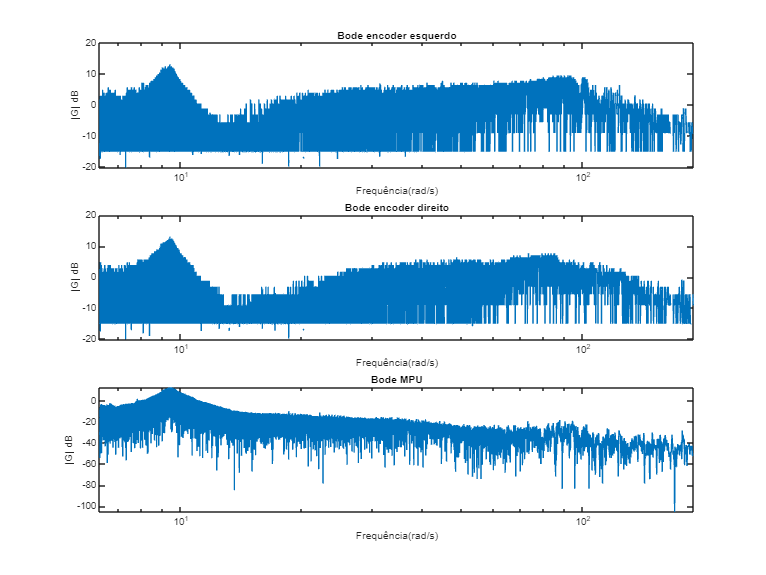

Declvel = 20*log10(abs(lvel));
Decrvel = 20*log10(abs(rvel));
Decthetavel = 20*log10(abs(thetavel));

freq_rad = 2*pi*(f1);

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)*2]);
clear pos

subplot(3,1,1)
semilogx(freq_rad, Declvel)
title("Bode encoder esquerdo")
xlabel(l_frad)
ylabel(l_gdec)


subplot(3,1,2)
semilogx(freq_rad, Decrvel)
title("Bode encoder direito")
xlabel(l_frad)
ylabel(l_gdec)

subplot(3,1,3)
semilogx(freq_rad, Decthetavel)
title("Bode MPU")
xlabel(l_frad)
ylabel(l_gdec)

#### Modelos de velocidade a partir dos dados de velocidade

K_l = -max(lvel) / max(u1)

K_l = -4.5115

K_r = -max(rvel) / max(u1)

K_r = -4.5115

K_theta = -max(thetavel) / max(u1)

K_theta = -4.3369


left = iddata(lvel, u1, ts);
rigth = iddata(rvel, u1, ts);
mpu = iddata(thetavel, u1, ts);

G_l = tfest(left, 2, 1)

G_l =
 
  From input "u1" to output "y1":
    -3.286 s - 0.9111
  ----------------------
  s^2 + 0.9533 s + 81.45
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "left".
Fit to estimation data: 35.76%                   
FPE: 0.4731, MSE: 0.4727                         
 
Model Properties


G_r = tfest(rigth, 2, 1)

G_r =
 
  From input "u1" to output "y1":
     -3.282 s - 2.338
  ----------------------
  s^2 + 0.9831 s + 81.76
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "rigth".
Fit to estimation data: 41.3%                     
FPE: 0.3423, MSE: 0.342                           
 
Model Properties


G_theta = tfest(mpu, 2, 1)

G_theta =
 
  From input "u1" to output "y1":
    -3.467 s - 5.669
  ---------------------
  s^2 + 1.008 s + 82.65
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "mpu".
Fit to estimation data: 69.71%                  
FPE: 0.07266, MSE: 0.07259                      
 
Model Properties


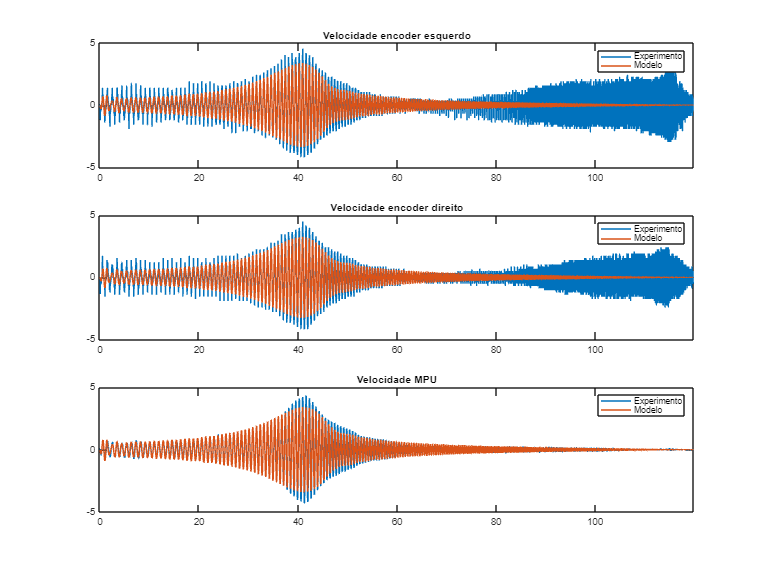


tt = 0:ts:length(u1)*ts-ts;
idx = (1:length(tt));

y_v_l = lsim(G_l, u1, tt);
y_v_r = lsim(G_r, u1, tt);
y_v_theta = lsim(G_theta, u1, tt);

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)*2]);
clear pos

subplot(3,1,1)
plot(tt(idx), lvel(idx))
title("Velocidade encoder esquerdo")
hold on
plot(tt(idx), y_v_l(idx))
xlim([tt(idx(1)) tt(idx(end))])
legend("Experimento", "Modelo")

subplot(3,1,2)
plot(tt(idx), rvel(idx))
title("Velocidade encoder direito")
hold on
plot(tt(idx), y_v_r(idx))
xlim([tt(idx(1)) tt(idx(end))])
legend("Experimento", "Modelo")

subplot(3,1,3)
plot(tt(idx), thetavel(idx))
title("Velocidade MPU")
hold on
plot(tt(idx), y_v_theta(idx))
xlim([tt(idx(1)) tt(idx(end))])
legend("Experimento", "Modelo")

#### Bode dos experimentos x bode dos modelos de velocidade obtidos pela velocidade

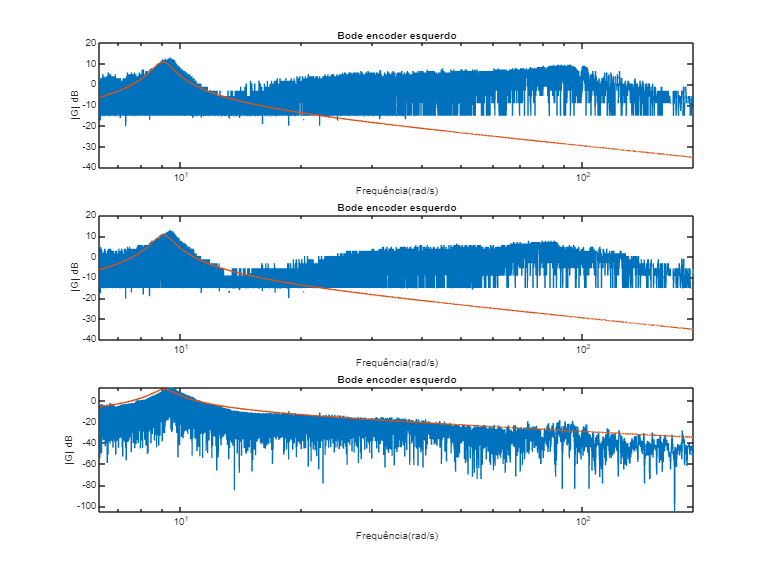

W = linspace(min(freq_rad), max(freq_rad), length(freq_rad));
[MAG,PHASE,W] = bode(G_l, W);
MAG = squeeze(MAG);
MAG1 = 20*log10(MAG);

[MAG,PHASE,W] = bode(G_r, W);
MAG = squeeze(MAG);
MAG2 = 20*log10(MAG);

[MAG,PHASE,W] = bode(G_theta, W);
MAG = squeeze(MAG);
MAG3 = 20*log10(MAG);


figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)*2]);
clear pos

subplot(3,1,1)
semilogx(freq_rad, Declvel)
hold on
semilogx(W,MAG1)
xlim([min(freq_rad), max(freq_rad)])
title("Bode encoder esquerdo")
xlabel(l_frad)
ylabel(l_gdec)

subplot(3,1,2)
semilogx(freq_rad, Decrvel)
hold on
semilogx(W,MAG2)
xlim([min(freq_rad), max(freq_rad)])
title("Bode encoder esquerdo")
xlabel(l_frad)
ylabel(l_gdec)

subplot(3,1,3)
semilogx(freq_rad, Decthetavel)
hold on
semilogx(W,MAG3)
xlim([min(freq_rad), max(freq_rad)])
title("Bode encoder esquerdo")
xlabel(l_frad)
ylabel(l_gdec)

#### Modelos de velocidade a partir da posição

s = tf("s");
G_l = G_encoder_l*s

G_l =
 
  From input to output "y1":
         -3.422 s
  ----------------------
  s^2 + 0.9976 s + 81.26
 
Continuous-time transfer function.
Model Properties


a = zpk(G_l);
a.Z{1}, ...
a.P{1}, ...
a.K

ans = 0

ans =   -0.4988 + 9.0006i
  -0.4988 - 9.0006i


ans = -3.4221


G_r = G_encoder_r*s

G_r =
 
  From input to output "y1":
         -3.314 s
  ----------------------
  s^2 + 0.9968 s + 81.13
 
Continuous-time transfer function.
Model Properties


a = zpk(G_r);
a.Z{1}, ...
a.P{1}, ...
a.K

ans = 0

ans =   -0.4984 + 8.9934i
  -0.4984 - 8.9934i


ans = -3.3139


G_theta = G_mpu*s

G_theta =
 
  From input to output "y1":
         -3.177 s
  ----------------------
  s^2 + 0.9096 s + 81.02
 
Continuous-time transfer function.
Model Properties


a = zpk(G_theta);
a.Z{1}, ...
a.P{1}, ...
a.K

ans = 0

ans =   -0.4548 + 8.9898i
  -0.4548 - 8.9898i


ans = -3.1772

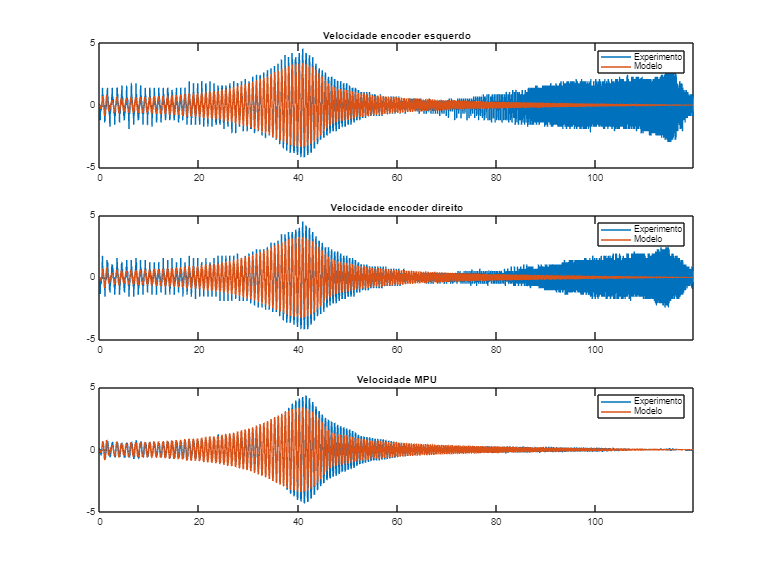


tt = 0:ts:length(u1)*ts-ts;
idx = (1:length(tt));

y_v_l = lsim(G_l, u1, tt);
y_v_r = lsim(G_r, u1, tt);
y_v_theta = lsim(G_theta, u1, tt);

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)*2]);
clear pos

subplot(3,1,1)
plot(tt(idx), lvel(idx))
title("Velocidade encoder esquerdo")
hold on
plot(tt(idx), y_v_l(idx))
xlim([tt(idx(1)) tt(idx(end))])
legend("Experimento", "Modelo")

subplot(3,1,2)
plot(tt(idx), rvel(idx))
title("Velocidade encoder direito")
hold on
plot(tt(idx), y_v_r(idx))
xlim([tt(idx(1)) tt(idx(end))])
legend("Experimento", "Modelo")

subplot(3,1,3)
plot(tt(idx), thetavel(idx))
title("Velocidade MPU")
hold on
plot(tt(idx), y_v_theta(idx))
xlim([tt(idx(1)) tt(idx(end))])
legend("Experimento", "Modelo")

#### Bode dos experimentos x bode dos modelos de velocidade obtidos pela posição

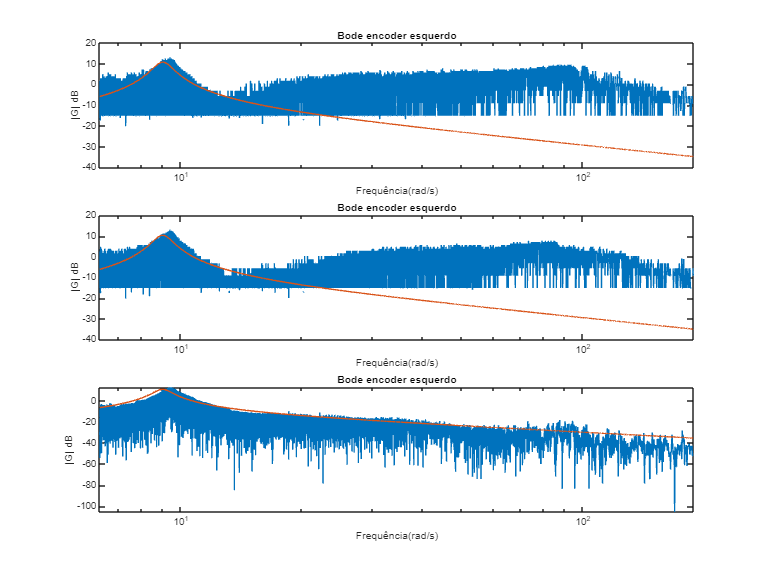

W = linspace(min(freq_rad), max(freq_rad), length(freq_rad));
[MAG,PHASE,W] = bode(G_l, W);
MAG = squeeze(MAG);
MAG1 = 20*log10(MAG);

[MAG,PHASE,W] = bode(G_r, W);
MAG = squeeze(MAG);
MAG2 = 20*log10(MAG);

[MAG,PHASE,W] = bode(G_theta, W);
MAG = squeeze(MAG);
MAG3 = 20*log10(MAG);


figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)*2]);
clear pos

subplot(3,1,1)
semilogx(freq_rad, Declvel)
hold on
semilogx(W,MAG1)
xlim([min(freq_rad), max(freq_rad)])
title("Bode encoder esquerdo")
xlabel(l_frad)
ylabel(l_gdec)

subplot(3,1,2)
semilogx(freq_rad, Decrvel)
hold on
semilogx(W,MAG2)
xlim([min(freq_rad), max(freq_rad)])
title("Bode encoder esquerdo")
xlabel(l_frad)
ylabel(l_gdec)

subplot(3,1,3)
semilogx(freq_rad, Decthetavel)
hold on
semilogx(W,MAG3)
xlim([min(freq_rad), max(freq_rad)])
title("Bode encoder esquerdo")
xlabel(l_frad)
ylabel(l_gdec)

G_theta

G_theta =
 
  From input to output "y1":
         -3.177 s
  ----------------------
  s^2 + 0.9096 s + 81.02
 
Continuous-time transfer function.
Model Properties


zpk(G_theta)

ans =
 
  From input to output "y1":
         -3.1772 s
  -----------------------
  (s^2 + 0.9096s + 81.02)
 
Continuous-time zero/pole/gain model.
Model Properties


zeros = ans.Z{1}, ...
polos = ans.P{1}, ...
K_corpo = ans.K

zeros = 0

polos =   -0.4548 + 8.9898i
  -0.4548 - 8.9898i


K_corpo = -3.1772

polos(1) + polos(2)

ans = -0.9096

omega = sqrt(polos(1) * polos(2))

omega = 9.0013

zeta = -(polos(1) + polos(2)) / (2 * omega)

zeta = 0.0505

K_corpo = K_corpo/omega^2

K_corpo = -0.0392